### Plot ship tracking parameters for IEEE paper

1 x 2 with range and speed

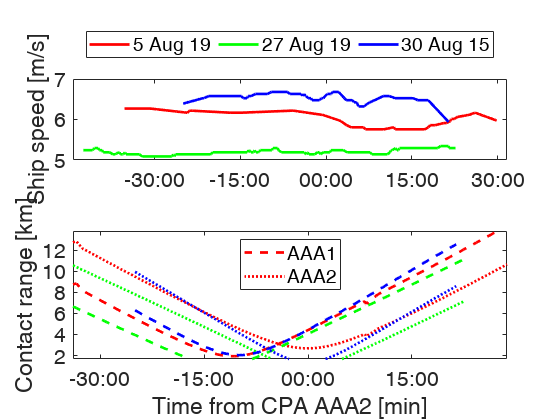

tog = struct with fields:
         VOI: 'OcEnd-AAA2-05Aug19'
    filetype: 'hdf5'
      calHph: 'yes'
     tlModel: 'geo'
      saveOn: 'yes'
      numHph: 48


tog = struct with fields:
         VOI: 'OcEnd-AAA2-27Aug19'
    filetype: 'hdf5'
      calHph: 'yes'
     tlModel: 'geo'
      saveOn: 'yes'
      numHph: 48


tog = struct with fields:
         VOI: 'OcEnd-AAA2-30Aug'
    filetype: 'hdf5'
      calHph: 'yes'
     tlModel: 'geo'
      saveOn: 'yes'
      numHph: 48


par.saveFigs = 0;
VOI_list = {'OcEnd-AAA1-05Aug19', 'OcEnd-AAA1-27Aug19', 'OcEnd-AAA1-30Aug'};
VOI_mkr = ['r', 'g', 'b']; 
par.fontSize = 20;
par.zoomLevel = 11;

figure('DefaultAxesPosition', [0.1, 0.1, 0.8, 0.8]);
formatOut = 'mm:ss';

for iVOI = 1:length(VOI_list)
tog.VOI = VOI_list{iVOI}
load(fullfile(par.procPath,tog.VOI));


%Speed
subplot(2,1,1)
plot(SPL.timeVector-SPL.timeVector(timeCPA),par.kts2ms*SPL.sog,VOI_mkr(iVOI),...
    'LineWidth',2);
%datetick('x'), xlim([min(SPL.timeVector) max(SPL.timeVector)])
ylabel('Ship speed [m/s]');%, ylim([6 7])
xtickformat(formatOut)
set(gca,'FontSize',par.fontSize)
legend('5 Aug 19', '27 Aug 19', '30 Aug 15','Location','northoutside','NumColumns',3)
hold on


%Range
subplot(2,1,2)
plot(SPL.timeVector-SPL.timeVector(timeCPA),1e-3*SPL.R1(:,par.refRecInd,1),VOI_mkr(iVOI)...
    ,'LineStyle','--','LineWidth',2);
hold on
plot(SPL.timeVector-SPL.timeVector(timeCPA),1e-3*SPL.R2(:,par.refRecInd,1),VOI_mkr(iVOI),...
    'LineStyle',':','LineWidth',2);
%datetick('x'), xlim([min(SPL.timeVector) max(SPL.timeVector)]), ylim([0 inf]);
ylabel('Contact range [km]') %, ylim([0 20])
xlabel('Time from CPA AAA2 [min]') %, ylim([0 20])
xtickformat(formatOut)
% AAA1str = sprintf('AAA1 CPA = %4.0f m',CPA.range(1));
% AAA2str = sprintf('AAA2 CPA = %4.0f m',CPA.range(2));
% legend(AAA1str,AAA2str,'Location','north'); legend boxoff
set(gca,'FontSize',par.fontSize)
legend('AAA1','AAA2','Location','north')
end

### Save figures

if par.saveFigs
    saveas(h, fullfile(par.figPath,'IEEE_Geospatial1x2.tif'));
    savefig(h, fullfile(par.figPath,'IEEE_Geospatial1x2'));
end

Unrecognized field name "saveFigs".